# (b)	Does it seem that there is a difference in the performance of the three cranes?

% 从第二问的问题角度来说 我们准备用one-way ANOVA来解决这个问题。

%% Reset environment
clear; clc; close all; % Clears workspace, command window, and closes figures

这一步是只是为了看数据的，若是第一题已经给出了相关观测结果，除了前三行和倒数第二片外剩下的都可以删除

1:是数据准备：把三组数据变成“长格式”——一列是所有的小时数，另一列是对应的起重机标签。原因是大多数比较组间差异的函数（例如 ANOVA、Kruskal–Wallis、箱线图）都接受“values + group labels”的形式，这样函数才能把每个观测值正确地归到对应的组里。做完这一步我们会立刻计算并输出每组的均值、中位数和标准差，因为这些数一方面提供直观印象（哪个看起来更好），另一方面能提示潜在问题：比如平均值和中位数差距大说明分布偏斜，标准差大说明不稳定或有异常。

2:可视化：画箱线图和均值柱状图（带标准差误差线）。箱线图能让我们一眼看到每组的中位数、四分位距以及异常点，直观感受哪台机器表现更高、更集中或者更分散；

% insert the data
crane14 = [140, 140, 112, 90, 32, 154, 359, 207, 61, 39, 40];
crane15 = [69, 14, 38, 94, 46, 36, 84, 106, 269, 445, 42, 108, 244, 92, 148, 303, 24, 328, 207, 260, 132, 56];
crane16 = [39, 135, 57, 31, 190, 90, 293, 151, 26, 77, 82, 156, 328, 92, 138, 47, 45];

% Data basic visulization
stats_mean = [mean(crane14), mean(crane15), mean(crane16)];
stats_median = [median(crane14), median(crane15), median(crane16)];
stats_std = [std(crane14), std(crane15), std(crane16)];
stats_var = [var(crane14), var(crane15), var(crane16)];
stats_n = [length(crane14), length(crane15), length(crane16)];

% 创建表格
Crane = ['Crane 14'; 'Crane 15'; 'Crane 16']; 
N = stats_n'; 
Mean = stats_mean'; 
Median = stats_median'; 
StdDev = stats_std';
Variance = stats_var';


% 合并为表格
T = table(Crane, N, Mean, Median, StdDev, Variance);

% 显示结果
disp('-------------------- Descriptive Statistics ------------------');

-------------------- Descriptive Statistics ------------------


disp(T);

     Crane      N      Mean     Median    StdDev    Variance
    ________    __    ______    ______    ______    ________

    Crane 14    11    124.91     112      95.672     9153.1 
    Crane 15    22    142.95     100      117.93      13907 
    Crane 16    17    116.29      90      87.993     7742.7 



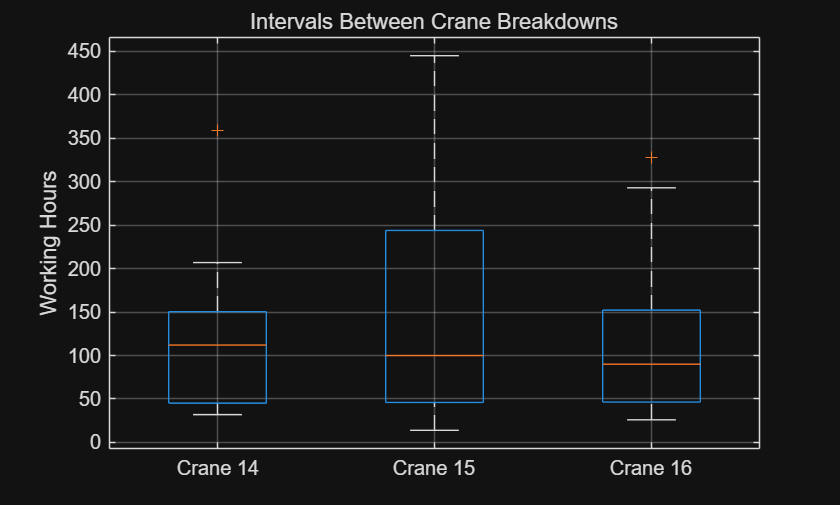


% Combine data into one vector and create a grouping variable
data = [crane14, crane15, crane16];
group = [repmat({'Crane 14'}, 1, length(crane14)), ...
         repmat({'Crane 15'}, 1, length(crane15)), ...
         repmat({'Crane 16'}, 1, length(crane16))];

% Create the box plot
figure;
boxplot(data, group);
title('Intervals Between Crane Breakdowns');
ylabel('Working Hours');
grid on;

One-way Anova will be applied in order to solve the question 2:

总体思路：我最先想到的就是把这些数字看成“可靠性/寿命”的观测值：数值越大表示这台机器在两次故障间能运行得越久，也就越可靠。我们的核心问题是判断三台起重机在这个指标上是否真有差别，区别不仅仅是看哪个平均大，而是要判断差异是否大到可以排除随机波动——也就是说是否具有统计学意义并且在实际运营上值得采取措施。为此我们的思路是先把数据整理成合适的格式，然后做一系列既能描述数据特征又能检验差异的分析，最后把统计结论翻译成对运营管理有用的建议。

Hypotheses:

H0: μ1 = μ2 = μ3 (all groups‘ means are equal)

H1: At least one group mean difers

因此接下来我要做正态性检验（QQ Plot 和 Shapiro–Wilk）并做方差齐性检验（ Levene）。如果三组数据都接近正态且方差齐，那么ANOVA是合适的；如果任何一条不满足，我们不能盲目用ANOVA，因为结果可能误导，此时应使用非参数检验——Kruskal–Wallis，它不要求正态分布且对异常值更健壮

% 最常用的检测方法是单因素方差分析，但是ANOVA的前提条件是每组数据近似正态分布而且各组方差要相等

% 测试假设条件是否成立
% 检查数据是否成正态分布 
title_name = {'crane14', 'crane15', 'crane16'}

title_name = 1×3 cell 数组
    {'crane14'}    {'crane15'}    {'crane16'}


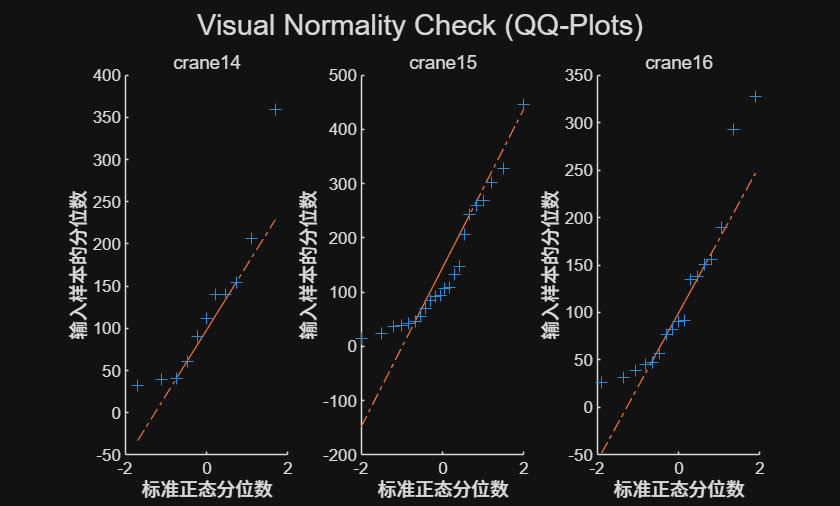


--- 正态性检验 (Shapiro-Wilk Test) ---
数据集: crane14
  p-value = 0.0382
  结论 (H=1): 拒绝 H0 (p < 0.05)。数据【不是】正态分布。

数据集: crane15
  p-value = 0.0156
  结论 (H=1): 拒绝 H0 (p < 0.05)。数据【不是】正态分布。

数据集: crane16
  p-value = 0.0166
  结论 (H=1): 拒绝 H0 (p < 0.05)。数据【不是】正态分布。

--- 检验结束 ---


function testNormality_sw(crane14, crane15, crane16, title_name)
% testNormality_SW: 使用 QQ-Plot 和 Shapiro-Wilk 检验来评估三组数据的正态性
    figure;%开始画图qqplot
    subplot(1,3,1); qqplot(crane14); title(title_name{1});
    subplot(1,3,2); qqplot(crane15); title(title_name{2});
    subplot(1,3,3); qqplot(crane16); title(title_name{3});

    sgtitle('Visual Normality Check (QQ-Plots)'); % 为qqplot图添加一个标题

    % 使用 swtest (Shapiro-Wilk Test)
    % [H, pValue, W] = swtest(data)
    % H0 表示无法拒绝原假设 (数据是正态的)
    % H1 表示拒绝原假设 (数据不是正态的)
    % pValue 是检验的 p 值

    [h14, p14] = swtest(crane14);%使用Shapiro-Wilk Test开始检测三数据
    [h15, p15] = swtest(crane15);
    [h16, p16] = swtest(crane16);

    fprintf('\n--- 正态性检验 (Shapiro-Wilk Test) ---\n');%开始输出正态性检测结果
    %我们将使用 5% (alpha = 0.05) 的显著性水平进行判断 
    %如果p<0.05 那么该数据就不是正态分布 
    %如果p>0.05 那么该数据就是正态分布

    % 先观察Crane 14 结果
    fprintf('数据集: %s\n', title_name{1});
    fprintf('  p-value = %.4f\n', p14);
    if h14 == 1
        fprintf('  结论 (H=%d): 拒绝 H0 (p < 0.05)。数据【不是】正态分布。\n', h14);
    else
        fprintf('  结论 (H=%d): 无法拒绝 H0 (p >= 0.05)。数据【符合】正态分布。\n', h14);
    end

    % Crane 15 结果
    fprintf('\n数据集: %s\n', title_name{2});
    fprintf('  p-value = %.4f\n', p15);
    if h15 == 1
        fprintf('  结论 (H=%d): 拒绝 H0 (p < 0.05)。数据【不是】正态分布。\n', h15);
    else
        fprintf('  结论 (H=%d): 无法拒绝 H0 (p >= 0.05)。数据【符合】正态分布。\n', h15);
    end

    % Crane 16 结果
    fprintf('\n数据集: %s\n', title_name{3});
    fprintf('  p-value = %.4f\n', p16);
    if h16 == 1
        fprintf('  结论 (H=%d): 拒绝 H0 (p < 0.05)。数据【不是】正态分布。\n', h16);
    else
        fprintf('  结论 (H=%d): 无法拒绝 H0 (p >= 0.05)。数据【符合】正态分布。\n', h16);
    end
    
    fprintf('\n--- 检验结束 ---\n');
end

   %现在开始观察三组数据的方差齐性，用lenvene
function testHomogeneity(data, group)
% testHomogeneity 检验多组数据的方差齐性（Levene 检验）
    [p_levene, stats] = vartestn(data(:), group, ...
        'TestType','LeveneAbsolute', 'Display','off');

    fprintf('\n--- Homogeneity of Variance (Levene''s Test) ---\n');
    fprintf('p-value = %.4f\n', p_levene);
    
    %我们将使用 5% (alpha = 0.05) 的显著性水平进行判断 
    %如果p<0.05 那么该数据方差不齐 
    %如果p>0.05 那么该数据方差齐
    if p_levene < 0.05
        disp('注意：方差不齐 (p < 0.05)。');
    else
        disp('方差齐性假设成立 (p >= 0.05)。');
    end
end

% 有三组数据 crane14, crane15, crane16
title_name = {'crane14', 'crane15', 'crane16'};
testNormality_sw(crane14, crane15, crane16, title_name)


% 方差齐性检验
testHomogeneity(data', group);


--- Homogeneity of Variance (Levene's Test) ---
p-value = 0.2708
方差齐性假设成立 (p >= 0.05)。


从以上函数输出结果可知 QQPlot上所有数据的结果都偏离直线 正态性明显不足 数据成中强度右偏态 因此我们使用sqr    函数或者log函数来对数据做变换, sqrt 函数适合中等强度右偏 log函数适合高强度右偏 所以我们采用sqrt函数来进行数据变换 

**sqrt**** (平方根) - 中等强度变换**

- **作用：** 这是一个**中等强度**的变换。它能有效地“拉回”中等程度的右偏长尾。

- **何时使用：** 当你的数据是**中度右偏**时，或者当数据是**计数（count）**类型时（例如 Q2.ii 中的“故障次数”），平方根变换非常常用。

- **限制：** 你的数据必须 >=0。

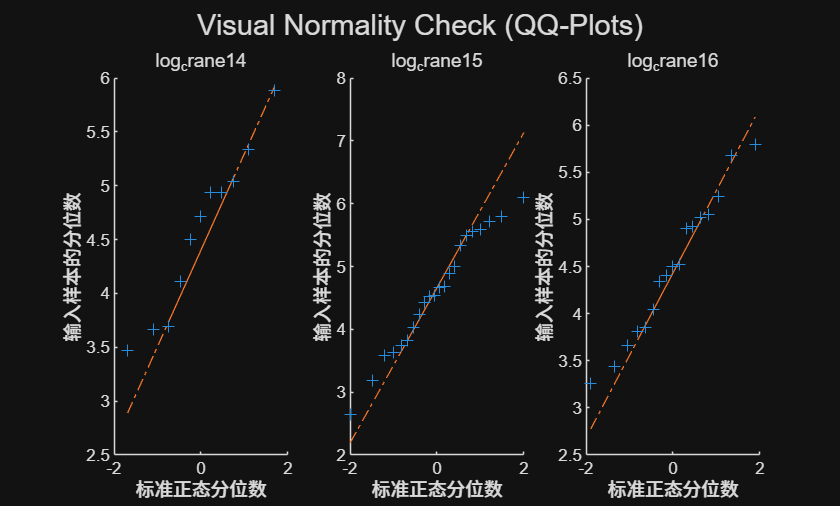


--- 正态性检验 (Shapiro-Wilk Test) ---
数据集: log_crane14
  p-value = 0.6764
  结论 (H=0): 无法拒绝 H0 (p >= 0.05)。数据【符合】正态分布。

数据集: log_crane15
  p-value = 0.7528
  结论 (H=0): 无法拒绝 H0 (p >= 0.05)。数据【符合】正态分布。

数据集: log_crane16
  p-value = 0.8149
  结论 (H=0): 无法拒绝 H0 (p >= 0.05)。数据【符合】正态分布。

--- 检验结束 ---


% 加个平方根尝试使其满足假设
%data_sqrt = sqrt(data);
%重新用QQPlot图来直观感受正态性分布
%sqrt_title_name = {'sqrt_crane14', 'sqrt_crane15', 'sqrt_crane16'};
%testNormality_sw(sqrt(crane14), sqrt(crane15), sqrt(crane16), sqrt_title_name);
% 方差齐性检验
%testHomogeneity(data_sqrt', group);

data_log = log(data);
log_title_name = {'log_crane14', 'log_crane15', 'log_crane16'};
testNormality_sw(log(crane14), log(crane15), log(crane16), log_title_name);


% 方差齐性检验
testHomogeneity(data_log', group);


--- Homogeneity of Variance (Levene's Test) ---
p-value = 0.6001
方差齐性假设成立 (p >= 0.05)。


至此，前面提到的假设条件均已满足，接下来是完成ANOVA步骤

下一步需要做的：

- 确定最后输出的p值是否是合理的

- 应用两次One-Way Anova，一次是组间差异/组内差异的值来计算，还有一次是直接调用Matlab库里面的One-Way Anova库，最后两两比较

- 确定是否需要使用Post-Hoc检验，因为这个正常来说是p<0.05的时候才需要使用的 （先不加了）

现在是调用MATLAB内置的函数计算ANOVA

% 执行单因素方差分析
[p, tbl, stats] = anova1(data_log', group, "off");

% 直接调用函数
anovaTable = cell2table(tbl(2:end,:), 'VariableNames', tbl(1,:));
disp('Built-in Function One-way ANOVA Results');

Built-in Function One-way ANOVA Results


anovaTable

anovaTable = 3×6 table
      来源        SS       df         MS              F            p 值(F)   
    ________    _______    __    ____________    ____________    ____________

    {'组'  }    0.10215     2    {[  0.0511]}    {[  0.0727]}    {[  0.9299]}
    {'误差'}     32.997    47    {[  0.7021]}    {0×0 double}    {0×0 double}
    {'合计'}     33.099    49    {0×0 double}    {0×0 double}    {0×0 double}



% 查看结果
fprintf('\nP Value of One-Way ANOVA\n');


P Value of One-Way ANOVA


fprintf('p-value = %.4f\n', p);

p-value = 0.9299


手动计算One-Way Anova (后期可以加一些公式的截图上去)

% --- 1. 数据变换 (Data Transformation) ---
%
% 目的: 对三组原始数据 (crane14, crane15, crane16) 应用自然对数 (log) 变换。
%
% 为什么: 这是执行 ANOVA 前的准备步骤。我们之前的正态性检验 (swtest) 
%         显示数据是右偏的 (non-normal)。'log' 变换可以"压缩"
%         较长的右尾，使数据分布更接近正态分布，以满足 ANOVA 的假设。
%         (注意: 如果原始数据包含 0，应使用 log(crane + 1))

log_crane14 = log(crane14);
log_crane15 = log(crane15);
log_crane16 = log(crane16);
%
% 结果: 得到了三个新的变量 'log_crane14', 'log_crane15', 'log_crane16'。
%      后续所有计算都将基于这些【变换后】的数据。

% --- 2. 数据重组 (Data Reshaping) ---
%
% 目的: 将三个独立的组向量合并成两个变量：一个长数据向量 (data) 
%         和一个对应的分组向量 (group)。
%
% 为什么: 这是在 MATLAB 中进行 ANOVA (无论是手动还是使用函数) 的标准格式。
%         - 'data' 向量包含了所有的数据点。
%         - 'group' 向量告诉 MATLAB 每个数据点分别属于哪一组 ('crane14', 'crane15' 等)。
%         - (我们使用 (:) 来确保数据是列向量，防止维度错误)。

data = [log_crane14(:); log_crane15(:); log_crane16(:)];
group = [repmat({'crane14'},numel(log_crane14),1);
         repmat({'crane15'},numel(log_crane15),1);
         repmat({'crane16'},numel(log_crane16),1)];
%
% 结果: 'data' (N x 1 向量) 和 'group' (N x 1 元胞数组)。

% --- 3. 计算基本统计量 (Basic Statistics) ---
%
% 目的: 计算后续 ANOVA 手动计算所需的所有基本值。
%
% 为什么:
%         - 'grandMean': 所有数据的总均值，用于计算 SSB。
%         - 'means': 一个包含 [mean1, mean2, mean3] 的向量，用于 SSB 和 SSW。
%         - 'ns': 一个包含 [n1, n2, n3] 的向量，存储每个组的样本大小，用于 SSB 和 df。

grandMean = mean(data);
means = [mean(log_crane14), mean(log_crane15), mean(log_crane16)];
ns = [numel(log_crane14), numel(log_crane15), numel(log_crane16)];
%
% 结果: 得到了计算 SSB 和 SSW 所需的所有组件。

% --- 4. 计算组间平方和 (SSB - Sum of Squares Between) ---
%
% 目的: 量化由 "组与组之间" 的差异所引起的变异 (即"信号")。
%
% 为什么: 这是 ANOVA 的核心。我们计算每个组的均值 (means) 与总均值 (grandMean) 
%         的差异，将其平方 (使其为正)，然后按该组的样本数 (ns) 
%         进行加权。'.*' 是 MATLAB 的元素级乘法。

SSB = sum(ns.*(means-grandMean).^2);
%
% 结果: 'SSB' 是一个标量，代表组间变异。
%      (注意: 我已删除了你代码中覆盖此值的、使用未定义变量的第二个 SSB 计算)。

% --- 5. 计算组内平方和 (SSW - Sum of Squares Within) ---
%
% 目的: 量化由 "组内部" 的随机波动所引起的变异 (即"噪音"或"误差")。
%
% 为什么: 我们计算每个组的内部变异。对于每一组 (如 log_crane14)，
%         我们计算每个数据点与它【自己组的均值】(means(1)) 之间的差异，
%         将其平方，然后将所有组的这些平方和加起来。

SSW = sum((log_crane14 - means(1)).^2) + ... % 'crane14' 组内的变异
      sum((log_crane15 - means(2)).^2) + ... % 'crane15' 组内的变异
      sum((log_crane16 - means(3)).^2);      % 'crane16' 组内的变异
%
% 结果: 'SSW' 是一个标量，代表组内（误差）变异。

% --- 6. 计算自由度 (Degrees of Freedom, df) ---
%
% 目的: 计算 F 检验所需的 "组间自由度" (df1) 和 "组内自由度" (df2)。
%
% 为什么: 为了公平比较 SSB 和 SSW，我们需要用自由度来"平均"它们。
%         - 'k': 组的数量 (3)。
%         - 'N': 总样本数。
%         - df_between (df1) = k - 1
%         - df_within (df2)  = N - k

k = length(ns);       % 组的数量 (等于 3)
N = sum(ns);          % 总样本数 (N = n1 + n2 + n3)
df_between = k - 1;   % 组间自由度
df_within = N - k;    % 组内自由度
%
% 结果: 得到了 'df_between' (df1) 和 'df_within' (df2)。

% --- 7. 计算均方 (MS - Mean Squares) ---
%
% 目的: 计算 "组间均方" (MSB) 和 "组内均方" (MSW)。
%
% 为什么: 均方是"标准化的"平方和（即平均平方和）。
%         - MSB (信号) = SSB / df_between
%         - MSW (噪音/误差) = SSW / df_within

MSB = SSB / df_between;
MSW = SSW / df_within;
%
% 结果: 'MSB' 和 'MSW' 是计算 F 值的两个直接分量。

% --- 8. 计算 F 统计量和 p 值 (F-Statistic and p-value) ---
%
% 目的: 计算最终的 F 统计量和 p 值，以做出统计决策。
%
% 为什么:
%         - F_manual = MSB / MSW (信号与噪音的比率)。
%         - p_manual = 我们使用 F 分布的累积分布函数 'fcdf' 来计算
%           观测到我们这个 F 值 (或更极端) 的概率。
%           我们用 '1 - fcdf(...)' 来获取 F 分布的右尾概率。

F_manual = MSB / MSW;
p_manual = 1 - fcdf(F_manual, df_between, df_within);
%
% 结果: 'F_manual' 是我们的 F 统计量，'p_manual' 是对应的 p 值。

% --- 9. (新增) 运行 MATLAB 内置函数以供比较 ---
%
% 目的: 运行 MATLAB 的标准 'anova1' 函数，以验证我们的手动计算是否正确。
%
% 为什么: 这是最好的调试方法。如果我们手算的结果与函数计算的结果一致，
%         我们就知道我们的逻辑是 100% 正确的。
%         'anova1' 返回 p 值 (p_func) 和一个包含 F 值的表格 (anovaTable)。
%         'Display', 'off' 阻止 'anova1' 自动弹出绘图窗口。

[p_func, anovaTable] = anova1(data, group, 'off');
%
% 结果: 'p_func' 是函数计算的 p 值，'anovaTable' 是 ANOVA 摘要表。

% --- 10. 显示手动 ANOVA 表 (Display Manual ANOVA Table) ---
%
% 目的: 以标准 ANOVA 表格的形式，专业地展示我们手动计算的结果。
%
% 为什么: 纯数字（如 F=5.6）很难阅读。表格 (Table) 是一种
%         清晰、标准化的格式，用于在报告中呈现 ANOVA 结果。

Manual_anova_Table = table([SSB; SSW; (SSB+SSW)],[df_between; df_within; (N-1)], [MSB; MSW; NaN], [F_manual; NaN; NaN], [p_manual; NaN; NaN], ...
    'VariableNames', {'SS','df','MS','F_Value','P_Value'}, ...
    'RowNames', {'Between Groups (SSB)','Within Groups (SSW)','Total (SST)'});

disp('--- 手动计算的单因素 ANOVA 结果 ---');

--- 手动计算的单因素 ANOVA 结果 ---


disp(Manual_anova_Table);

                              SS       df       MS       F_Value    P_Value
                            _______    __    ________    _______    _______

    Between Groups (SSB)    0.10215     2    0.051075    0.07275    0.92994
    Within Groups (SSW)      32.997    47     0.70206        NaN        NaN
    Total (SST)              33.099    49         NaN        NaN        NaN



%
% 结果: 在命令行中打印出一个格式化的 ANOVA 表。

% --- 11. 比较与结论 (Compare and Conclude) ---
%
% 目的: 自动比较手动 p 值 (p_manual) 和函数 p 值 (p_func)，并
%         根据 0.05 的显著性水平 (alpha) 打印出最终结论。
%
% 为什么:
%         1. 验证: 检查 'p_func' 和 'p_manual' 是否几乎相等 (允许浮点误差)。
%         2. 决策: 如果 p < 0.05，我们拒绝原假设 (H0)，说明
%            至少有一个组的均值是不同的。
%         3. (修正: 你的代码使用了未定义的 'p'，我已将其修正为 'p_func')。

fprintf('\n--- 手动计算 vs MATLAB 函数结果对比 ---\n');


--- 手动计算 vs MATLAB 函数结果对比 ---


fprintf('手动计算: F = %.4f, p = %.6f\n', F_manual, p_manual);

手动计算: F = 0.0727, p = 0.929938


fprintf('函数计算: F = %.4f, p = %.6f\n', anovaTable{2,5}, p_func); % {2,5} 是 F 值

函数计算: F = 0.0727, p = 0.929938



if abs(p_func - p_manual) < 1e-6 % 检查两个 p 值是否 (几乎) 相等
    disp('*** 验证成功: 手动计算与函数结果一致。***');
    
    % 基于 p 值做出统计决策
    if p_func < 0.05
        disp('结论 (p < 0.05): 拒绝原假设 H0。');
        disp('至少有一个组的均值存在显著差异，需要进行事后检验 (Post-Hoc test)。');
    else
        disp('结论 (p >= 0.05): 无法拒绝原假设 H0。');
        disp('没有足够的证据表明各组均值之间存在显著差异。');
    end
else 
    disp('*** 警告: 手动计算与函数结果【不】一致，请检查代码！***');
end

*** 验证成功: 手动计算与函数结果一致。***


结论 (p >= 0.05): 无法拒绝原假设 H0。


没有足够的证据表明各组均值之间存在显著差异。


%
% 结果: 打印出最终的验证状态和统计结论。